## Inverse Design of a single segment

Given a load and a desired loaded curvature and loaded length, try to find the segment width and segment neutral length that takes on that shape under load.

**Desired variables:** loaded curvature, loaded length.

**Design variables:** segment width, segment neutral length.

**Questions:**

- What segment widths and neutral lengths will satisfy this?

- How many are there?

%1. Inverse design of a single two-muscle segment
rho = 0.03;
l_0 = 0.2;
arm_segment = ArmSegmentFactory.make_2d_2muscle(rho, l_0);
arm_segment.set_mechanics(GinaMuscleMechanics(l_0));

g_circ_right_goal = [0.18; 0; 0.5];
arm_segment.g_circ_right = g_circ_right_goal;

Q = [0; -3; 0];
Q_base = arm_segment.calc_external_reaction(Q, g_circ_right_goal);
rxn_goal = -Q_base;

[soln, res] = fsolve(@(g_circ_right) arm_segment.check_equilibrium([0; 80], Q, g_circ_right), [l_0; 0; 0])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


soln =     0.1762
         0
    0.5149


res = 1.0e-13 *

    0.1155
         0
   -0.0253


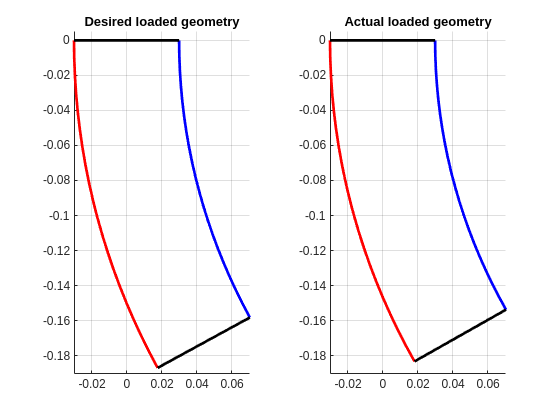

tl = tiledlayout(1, 2);
ax1 = nexttile;
arm_segment.g_circ_right = g_circ_right_goal;
Plotter2D.plot_arm_segment(arm_segment, ax1);
title("Desired loaded geometry")
grid on

ax2 = nexttile;
arm_segment.g_circ_right = soln;
Plotter2D.plot_arm_segment(arm_segment, ax2);
title("Actual loaded geometry")
grid on
linkaxes([ax1, ax2])

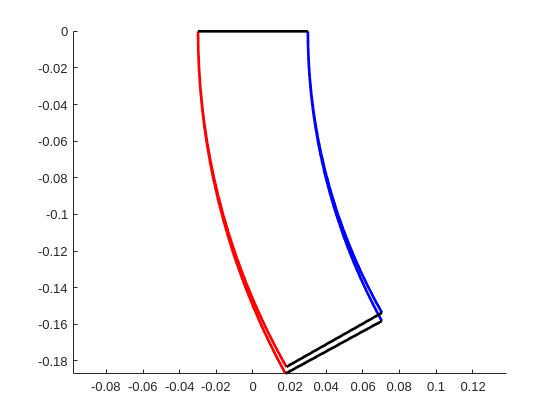

ax = axes(figure());
arm_segment.g_circ_right = g_circ_right_goal;
Plotter2D.plot_arm_segment(arm_segment, ax);
arm_segment.g_circ_right = soln;
Plotter2D.plot_arm_segment(arm_segment, ax);

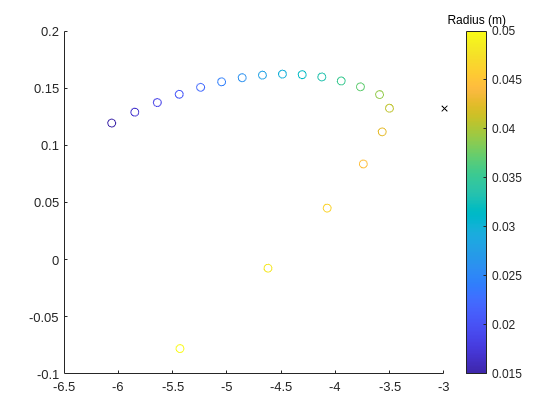

% For a constant l_0, find the best radius for reaching a reaction moment
N_rhos = 20;
rhos = linspace(0.015, 0.05, N_rhos);

mat_rxns = zeros(3, N_rhos);
for i = 1 : N_rhos
    % Calculate the internal reaction moment that the muscles would create
    % at that curvature.
    rho_i = rhos(i);

    segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0);
    segment_ij.set_mechanics(GinaMuscleMechanics(l_0));

    mat_rxns(:, i) = segment_ij.calc_internal_reaction([0; 80], g_circ_right_goal);
end

figure()
hold on
scatter(rxn_goal(1), rxn_goal(3), 'kx');
scatter(mat_rxns(1, :), mat_rxns(3, :), [], rhos);
cb = colorbar;
cb.Title.String = "Radius (m)";

N_rhos = 20;
N_ls = 20;
rhos = linspace(0.015, 0.05, N_rhos);
l_0s = linspace(0.19, 0.21, N_ls);

cell_rl = cell(N_rhos, N_ls);
cell_arm_segments = cell(N_rhos, N_ls);
cell_rxns = cell(N_rhos, N_ls);
cell_colors = cell(N_rhos, N_ls);
for i = 1 : N_rhos
    rho_i = rhos(i);
    for j = 1 : N_ls
        l_0_j = l_0s(j);
        % Calculate the internal reaction moment that the muscles would create
        % at that curvature.
        segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0_j);
        segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j));
    
        cell_arm_segments{i, j} = segment_ij;
        cell_rl{i, j} = [rho_i; l_0_j];
        cell_rxns{i, j} = segment_ij.calc_internal_reaction([0; 80], g_circ_right_goal);
        cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
    end
end

mat_rl = [cell_rl{:}];
mat_rxns = [cell_rxns{:}];
mat_hsv = [cell_colors{:}];
mat_rgb = hsv2rgb(mat_hsv');

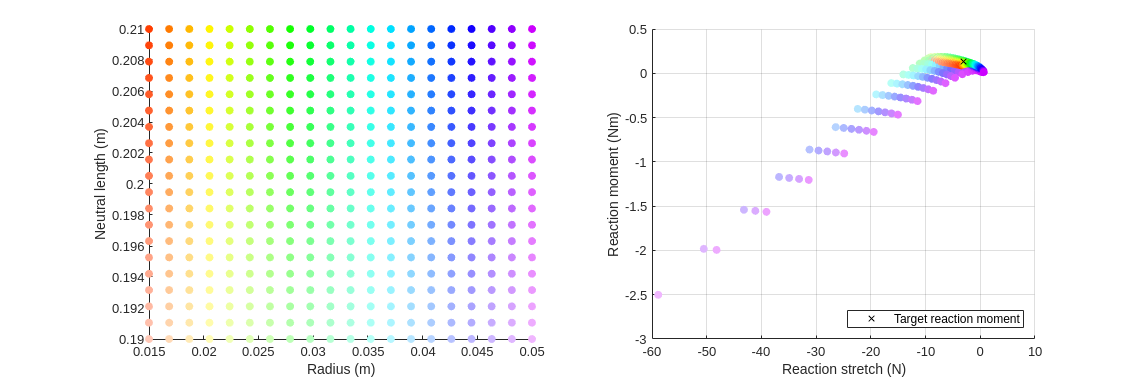

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius (m)");
ylabel("Neutral length (m)")

subplot(1, 2, 2);
hold on
scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
scatter(rxn_goal(1), rxn_goal(3), 'kx')

grid on
xlabel("Reaction stretch (N)")
ylabel("Reaction moment (Nm)")
legend(["", "Target reaction moment"], "location", "southeast")